# **Introductory script illustrating how to compute treeshrew cone mosaic excitation responses to an ISETBio scene.**

***This tutorial generates an ISETBio scene representing a Gabor stimulus as realized on a particular display, passes this scene through the default human optics, and computes cone mosaic excitation responses. The simulation parameters here are appropriate for human experiments. For tree-shrew specific parameters see t_treeShrewConeIsomerizationsFromSceneOnDisplay***

#### **See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

- `t_coneIsomerizationsFromSceneOnDisplay.mlx ` (parameters specific to the human visual system)

- t_opticTreeShrew.mlx (expore various optics params)

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# OUTLINE

 **   Step 1.** Create a presentation display and a low spatial frequency Gabor stimulus realized on that display

 **   Step 2.** Compute the optical image using the default treeshrew optics

   ** Step 3.** Create a treeshrew cone mosaic object and compute its isomerization response to the optical image for a 20 msec presentation

# **Step 1.** Create a presentation display and a Gabor stimulus realized on that display

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

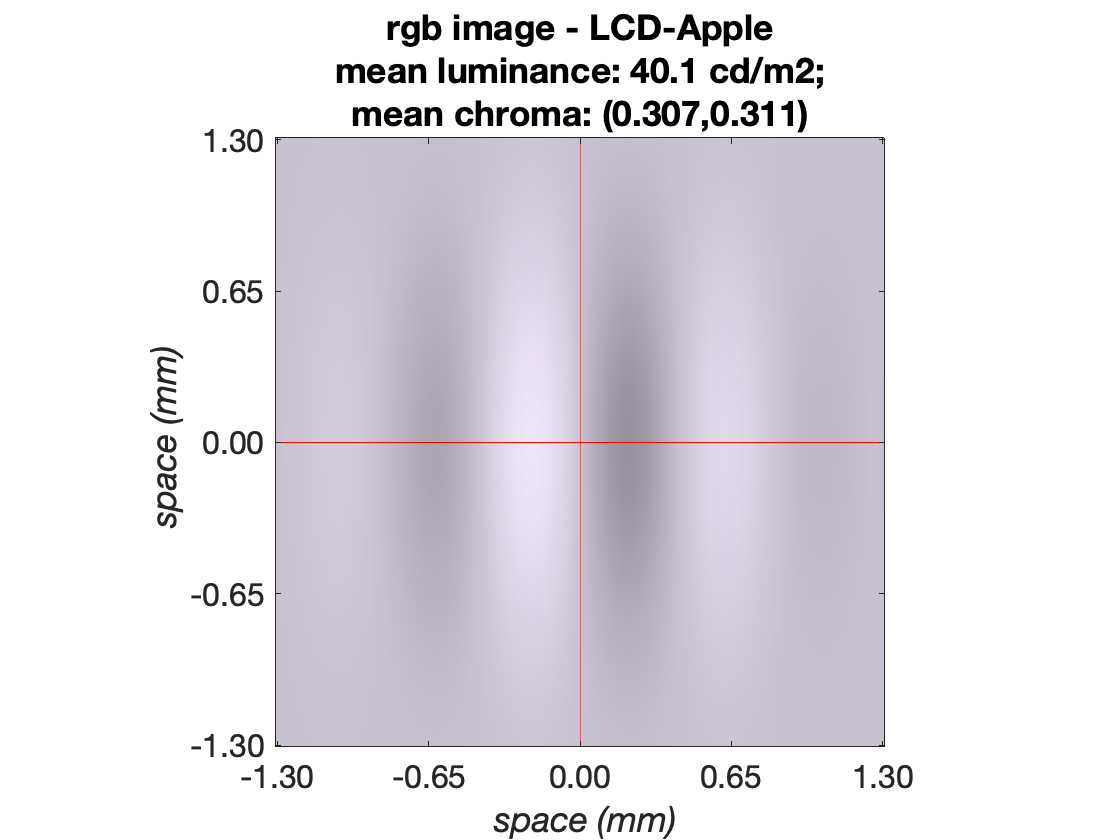

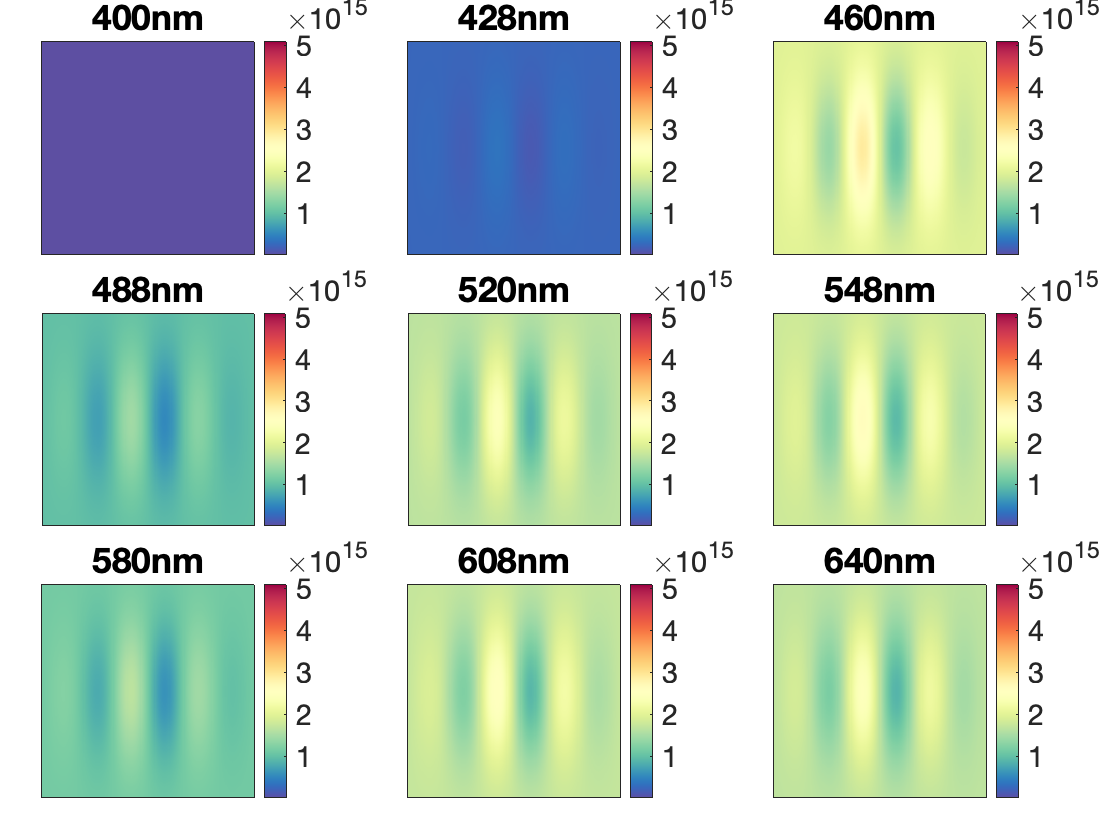

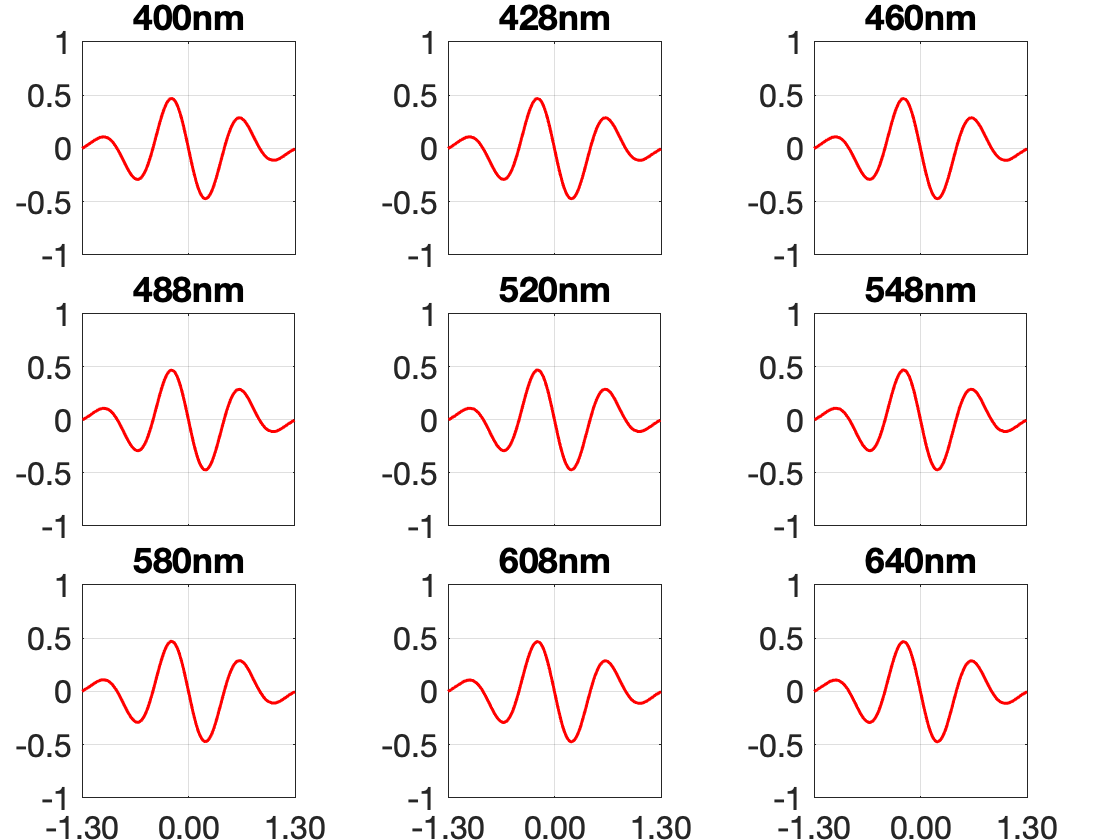

%% Create presentation display and place it 5 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 5/100);

%% parameter struct for a low spatial frequency Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 1.0, ... % 1.0 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 90, ...                    % spatial phase degrees
    'sizeDegs', 3.0, ...                    % 4 x 4 size
    'sigmaDegs', 0.7, ...                   % sigma of Gaussian envelope
    'contrast', 0.5,...                     % 0.5 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );


% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene, 'displayContrastProfiles', true);

# **Step 2.** Compute the optical image using the default TreeShrew optics

We employ the default treeshrew optics which are based on a Gaussian PSF. The scene is passed through the optics model to compute the retinal image.

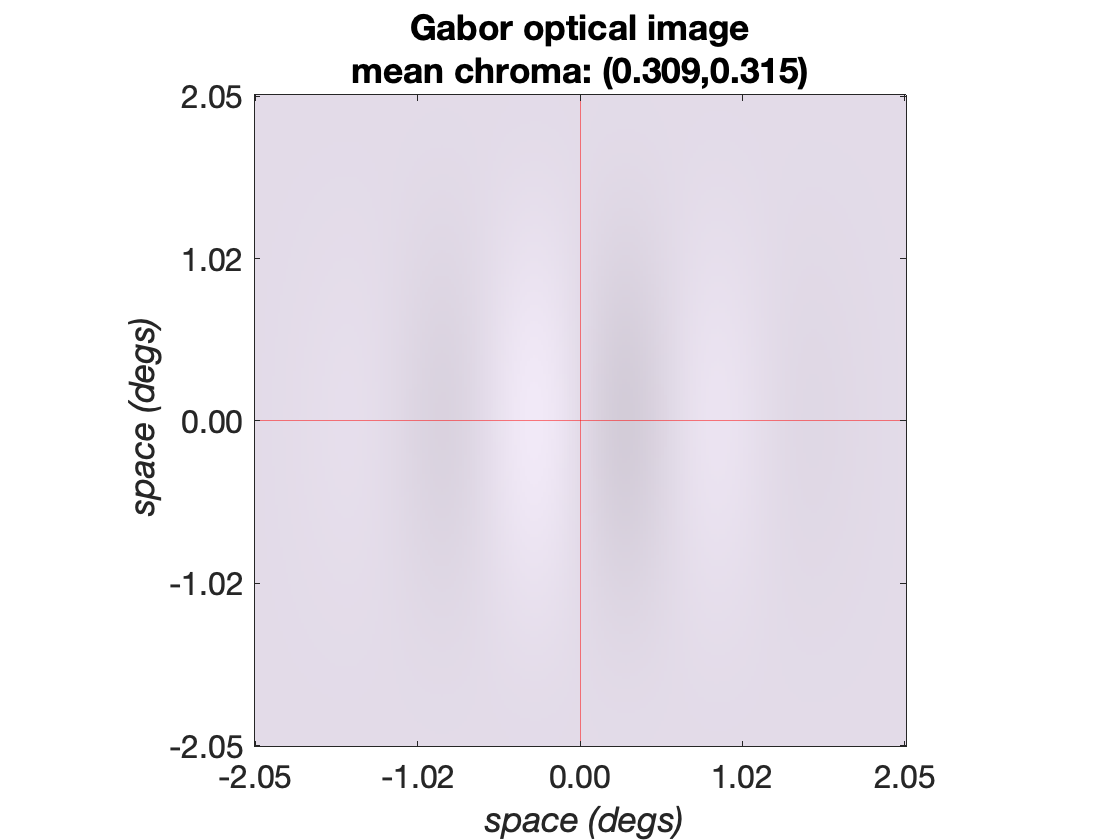

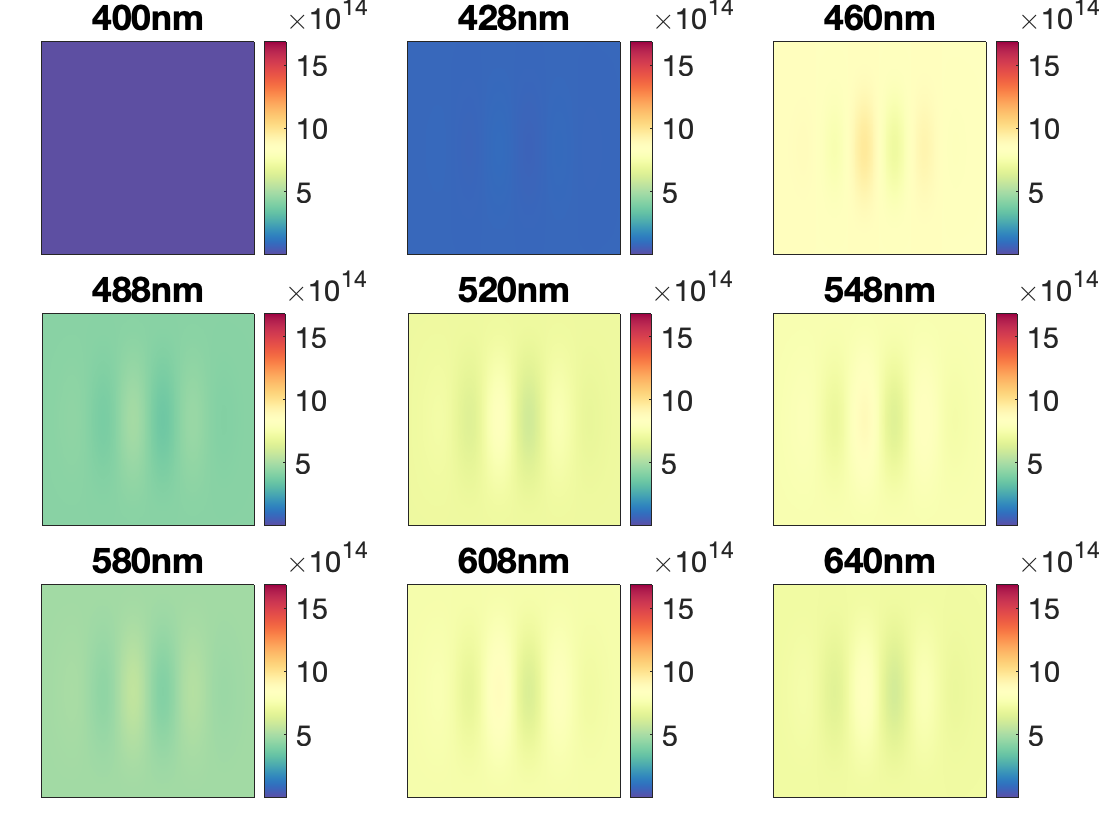

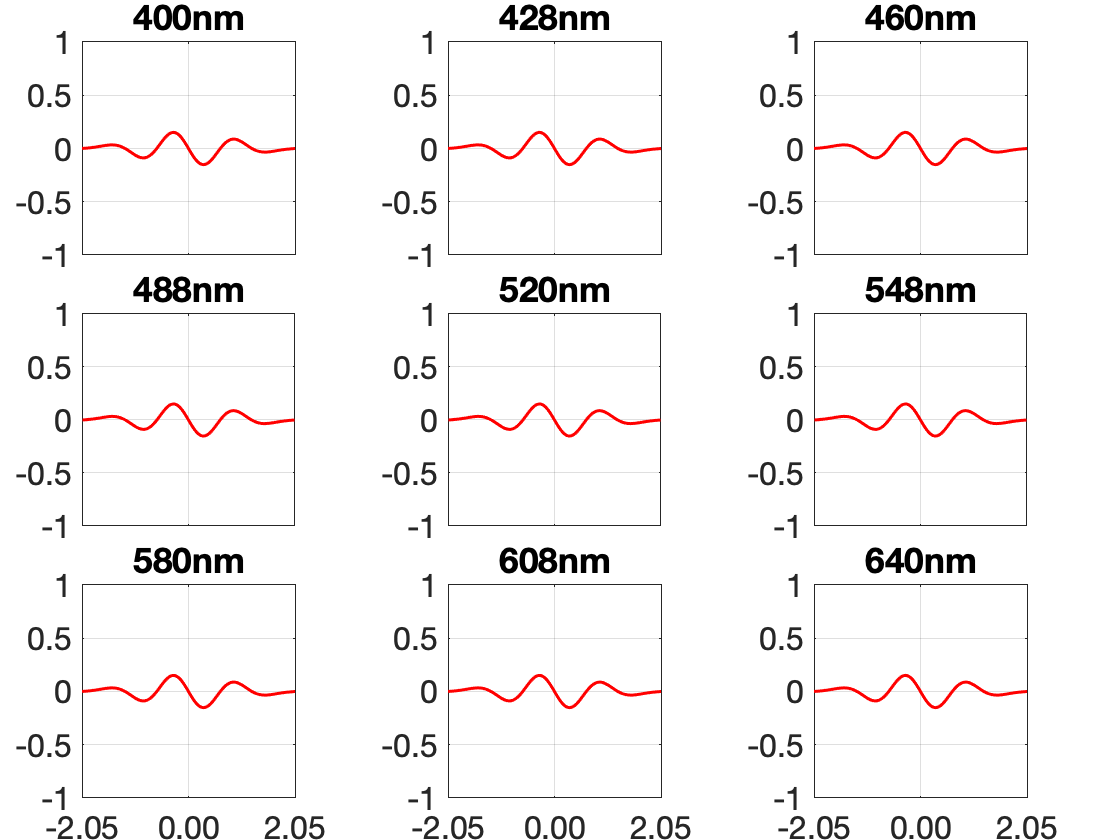

%% Generate default treeshrew optics
theOI = oiTreeShrewCreate();

%% Compute the retinal image
theOI = oiCompute(theOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theOI, 'displayRetinalContrastProfiles', true);

# **Step 3.** Generate the default TreeShrew cone mosaic

Generate and visualize the default three shrew cone mosaic

% Generate default treeshrew cone mosaic with a 5 msec integration time
theConeMosaic = coneMosaicTreeShrewCreate(...
     theOI.optics.micronsPerDegree, ...
    'fovDegs', 0.5*stimParams.sizeDegs*[1 1], ...
    'integrationTime', 5/1000);
theConeMosaic.displayInfo();
theConeMosaic.visualizeGrid('backgroundColor', [1 1 1]); 
theConeMosaic.micronsPerDegree
theConeMosaic.fov

# **Step 4.** Generate cone excitation responses to the optical image

### Step 4.1 Generate responses

Here we are generating some cone excitation response instances

nTrialsNum = 10;
emPath = zeros(nTrialsNum, 1, 2);
% Compute mosaic excitation responses
coneExcitations = theConeMosaic.compute(theOI, 'emPath', emPath);

### Step 4.2 Visualize results. 

We are visualizing the cone mosaic on the left, along with the first two response instances. All computed responses instances for cones located along the horizontal meridian are visualized on the bottom plot.

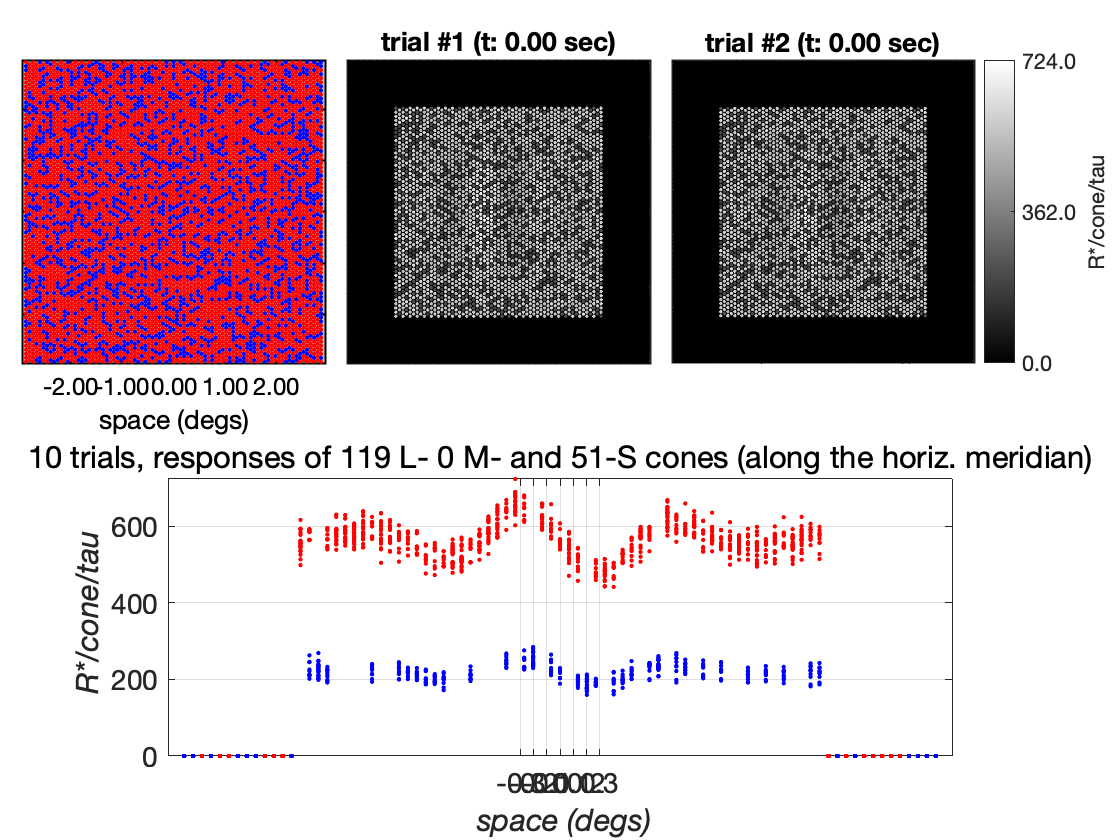

%% Visualize cone mosaic and its cone excitation responses
visualizeConeMosaicResponses(theConeMosaic, coneExcitations, 'R*/cone/tau');

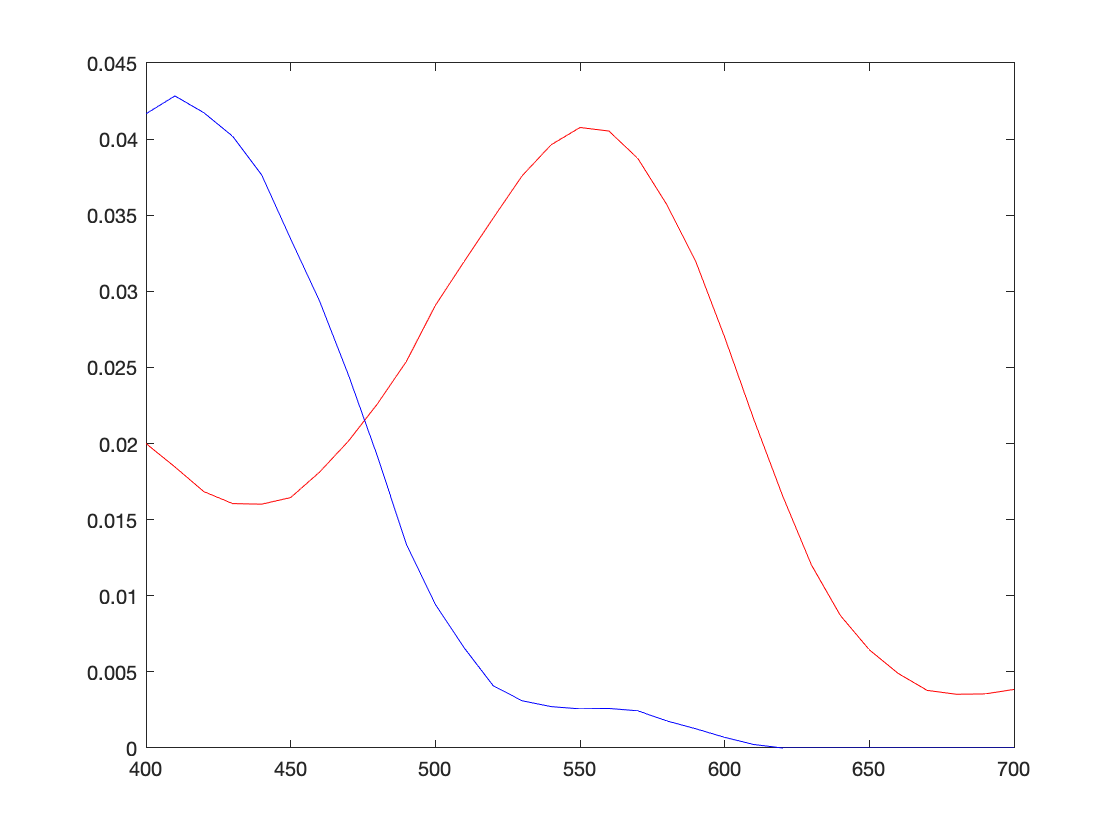


qe = theConeMosaic.qe;
wave = theConeMosaic.wave;
figure()
plot(wave, qe(:,1), 'r-');hold on;
plot(wave, qe(:,3), 'b-')